# Pierwsza Metoda Lapunova

## Układ mechaniczny


$$\ddot{y}(t) + b\dot{y}(t) + cy(t) + dy^{3}(t) = 0$$


warning off all
syms x1 x2 b c d
J = [0, 1; -c-3*d*x1^2, -b]

$$J = \left(\begin{array}{cc} 0 & 1\\ -3\,d\,{x_{1}}^{2}-c & -b \end{array}\right)$$

% P(0,0) lub d>0
J1 = [0 1; -c -b]

$$J1 = \left(\begin{array}{cc} 0 & 1\\ -c & -b \end{array}\right)$$

eig(J1)

$$ans = \left(\begin{array}{c} -\frac{b}{2}-\frac{\sqrt{b^{2}-4\,c}}{2}\\ \frac{\sqrt{b^{2}-4\,c}}{2}-\frac{b}{2} \end{array}\right)$$


% pozostałe 
J2 = [0 1; 2*c -b]

$$J2 = \left(\begin{array}{cc} 0 & 1\\ 2\,c & -b \end{array}\right)$$

eig(J2)

$$ans = \left(\begin{array}{c} -\frac{b}{2}-\frac{\sqrt{b^{2}+8\,c}}{2}\\ \frac{\sqrt{b^{2}+8\,c}}{2}-\frac{b}{2} \end{array}\right)$$

clear all
b = 0.5;
c = 0.6;
d = -0.7;

odefun = @(t, x)system31(t, x, b, c, d);
plotpp(odefun)
hold on
x_ = [];
y_ = [];

for x_1 = -10:0.1:10
    for x_2 = -10:0.1:10
        [t,y] = ode45 (@(t, x)system31(t, x, b, c, d), [0 100], [x_1 x_2] );
        if abs(y(end,1)) < 0.0001 && abs(y(end, 2)) < 0.0001 
            x_(end + 1) = x_1;
            y_(end + 1)= x_2;
        end
    end
end

arg = [];
first = [];
second = [];
for x_1 = x_
    arg(end + 1) = x_1;
    index = find(x_ == x_1);
    values = y_(index);
    first(end + 1) = min(values);
    second(end + 1) = max(values);
end

x_ = [arg,sort(arg, 'descend')];
y_ = [first, flip(second)];
p = fill (x_ ,y_ ,[0.7450 0.3010  0.9330],'FaceAlpha',0.3);
p.EdgeColor = [0.3010 0.7450 0.9330];
r = plot(0, 0, '.', 'Color', 'red')

r =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 0
              YData: 0

  Show all properties


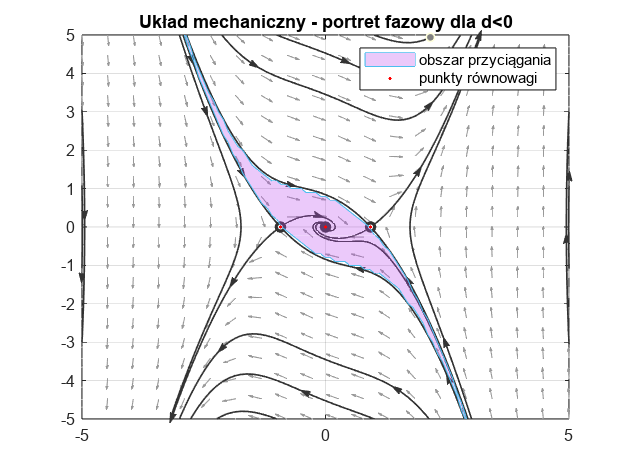

plot(sqrt(-c/d), 0, '.', 'Color', 'red')
plot(-sqrt(-c/d), 0, '.', 'Color', 'red')
title('Układ mechaniczny - portret fazowy dla d<0')
legend([p, r], ["obszar przyciągania", "punkty równowagi"])
hold off

d = 0.7;

odefun = @(t, x)system31(t, x, b, c, d);
plotpp(odefun)
hold on
r = plot(0, 0, '.', 'Color', 'red')

r =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 0
              YData: 0

  Show all properties


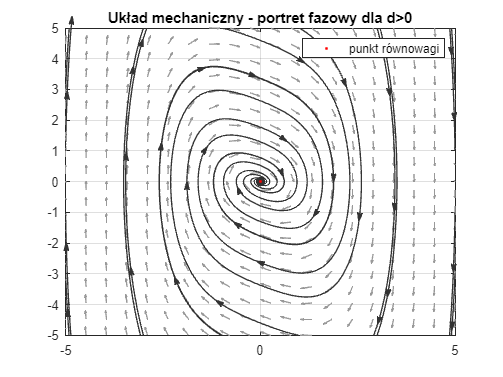

title('Układ mechaniczny - portret fazowy dla d>0')
legend(r, "punkt równowagi")
hold off

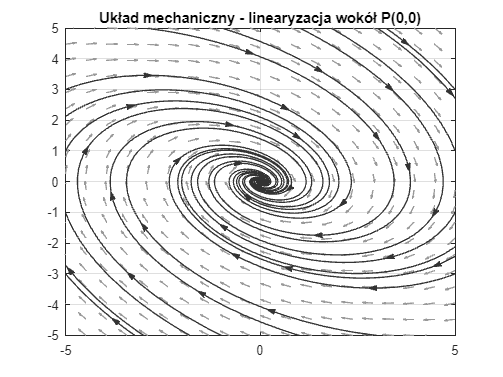

x0 = [0.1 0.1];
J = [0 1; -c -b];
plotpp(@(t, x)J*[x(1); x(2)])
title("Układ mechaniczny - linearyzacja wokół P(0,0)")

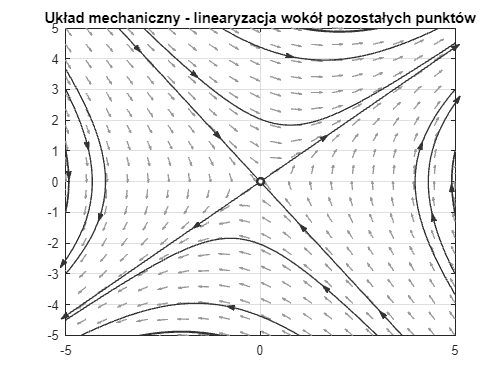

J = [0 1; 2*c -b];
plotpp(@(t, x)J*[x(1); x(2)])
title("Układ mechaniczny - linearyzacja wokół pozostałych punktów")

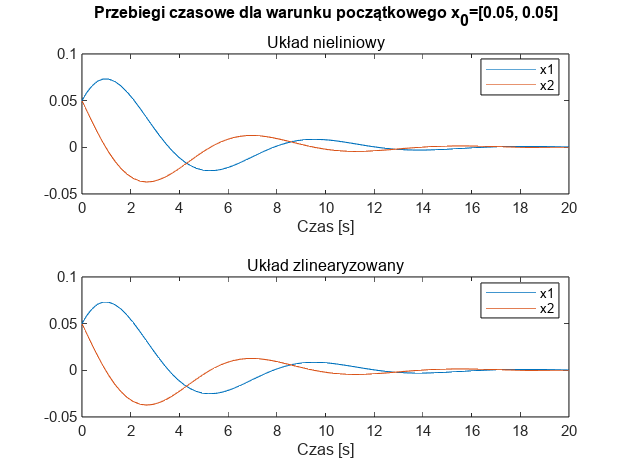

figure 
close all;
clear all;
sim_time = 20;
subplot(2,1,1)
b = 0.5;
c = 0.6;
d = -0.7;
x0=[0.05, 0.05];
[t, xx] = ode45(@(t,x) system31(t,x,b,c,d), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
x=[0,0];
A=[0, 1; -3*d*x(1)^2-c, -b];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
saveas(gcf,'mech_przeb_1.png')

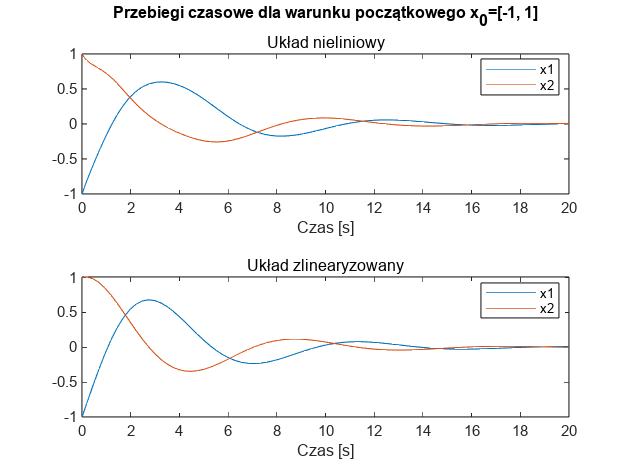

figure 
close all;
clear all;
subplot(2,1,1)
sim_time = 20;
b = 0.5;
c = 0.6;
d = -0.7;
x0=[-1, 1];
[t, xx] = ode45(@(t,x) system31(t,x,b,c,d), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
x=[0,0];
A=[0, 1; -3*d*x(1)^2-c, -b];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
saveas(gcf,'mech_przeb_2.png')

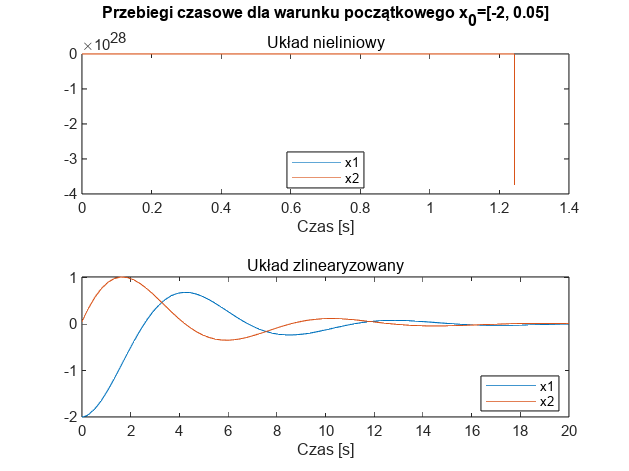

figure 
close all;
clear all;
sim_time = 20;
subplot(2,1,1)
b = 0.5;
c = 0.6;
d = -0.7;
x0=[-2, 0.05];
[t, xx] = ode45(@(t,x) system31(t,x,b,c,d), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
x=[0,0];
A=[0, 1; -3*d*x(1)^2-c, -b];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
saveas(gcf,'mech_przeb_3.png')

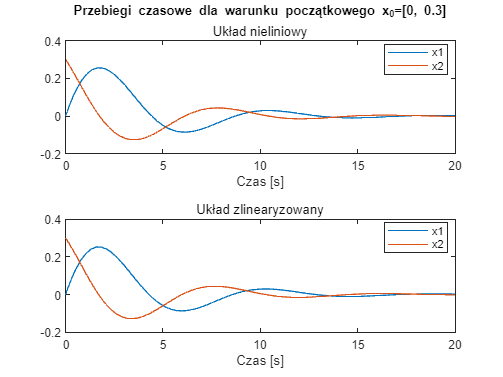

figure 
close all;
clear all;
sim_time = 20;
subplot(2,1,1)
b = 0.5;
c = 0.6;
d = -0.7;
x0=[0, 0.3];
[t, xx] = ode45(@(t,x) system31(t,x,b,c,d), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
x=[0,0];
A=[0, 1; -3*d*x(1)^2-c, -b];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

%saveas(gcf,'przebiegi14.png')

## Wahadło


$$\ddot{y}(t) + \frac{g}{l}\sin{y}(t) + \frac{c}{lm}\dot{y}(t) = 0$$


clear all
syms c l m g x1 x2
J = [0 1; -g/l*cos(x1) -c/l*m]

$$J = \left(\begin{array}{cc} 0 & 1\\ -\frac{g\,\cos\left(x_{1}\right)}{l} & -\frac{c\,m}{l} \end{array}\right)$$

% P(2kpi, 0)
J1 = [0 1; -g/l -c/(l*m)]

$$J1 = \left(\begin{array}{cc} 0 & 1\\ -\frac{g}{l} & -\frac{c}{l\,m} \end{array}\right)$$

eig(J1)

$$ans = \left(\begin{array}{c} -\frac{c+\sqrt{c^{2}-4\,g\,l\,m^{2}}}{2\,l\,m}\\ -\frac{c-\sqrt{c^{2}-4\,g\,l\,m^{2}}}{2\,l\,m} \end{array}\right)$$


% P((2k+1)pi, 0)
J2 = [0 1; g/l -c/(l*m)]

$$J2 = \left(\begin{array}{cc} 0 & 1\\ \frac{g}{l} & -\frac{c}{l\,m} \end{array}\right)$$

eig(J2)

$$ans = \left(\begin{array}{c} -\frac{c+\sqrt{c^{2}+4\,g\,l\,m^{2}}}{2\,l\,m}\\ -\frac{c-\sqrt{c^{2}+4\,g\,l\,m^{2}}}{2\,l\,m} \end{array}\right)$$

clear all
g = 9.81;
c = 2.5;
m = 5;
l = 5;

% P(2kpi, 0)
J1 = [0 1; -g/l -c/(l*m)]

J1 =          0    1.0000
   -1.9620   -0.1000


eig(J1)

ans =   -0.0500 + 1.3998i
  -0.0500 - 1.3998i



% P((2k+1)pi, 0)
J2 = [0 1; g/l -c/(l*m)]

J2 =          0    1.0000
    1.9620   -0.1000


eig(J2)

ans =     1.3516
   -1.4516


clear all
g = 9.81;
c = 2.5;
m = 5;
l = 5;

x0 = [-pi 2.4]; %jeden pełny obrót
x02 = [-pi 3]; %dwa pełne obroty
[t,x] = ode45(@(t,x) system38(t, x, c, l, m), [0 100], x0);
[t2,x2] = ode45(@(t,x) system38(t, x, c, l, m), [0 100], x02);

odefun = @(t, x)system38(t, x, c, l, m);
plotpp(odefun, 'xlim', [-5, 15], 'ylim', [-5, 5])
hold on
x_ = [];
y_ = [];

for x_1 = -15:0.1:15
    for x_2 = -15:0.1:15
        [t,y] = ode45 (@(t, x)system38(t, x, c, l, m), [0 100], [x_1 x_2] );
        if abs(y(end,1)) < 0.1 && abs(y(end, 2)) < 0.1 
            x_(end + 1) = x_1;
            y_(end + 1)= x_2;
        end
    end
end

arg = [];
first = [];
second = [];
for x_1 = x_
    arg(end + 1) = x_1;
    index = find(x_ == x_1);
    values = y_(index);
    first(end + 1) = min(values);
    second(end + 1) = max(values);
end

x_ = [arg,sort(arg, 'descend')];
y_ = [first, flip(second)];
p = fill(x_ ,y_ ,[0.7450 0.3010  0.9330],'FaceAlpha',0.3);
p.EdgeColor = [0.3010 0.7450 0.9330];
plot(0, 0, '.', 'Color', 'red')
plot(-2* pi, 0, '.', 'Color', 'red')
r = plot(2* pi, 0, '.', 'Color', 'red')

r =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 6.2832
              YData: 0

  Show all properties


plot(3* pi, 0, '.', 'Color', 'red')
m = plot(x(:, 1), x(:, 2), 'blue-')

m =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-3.1416 -2.9841 -2.8262 -2.6668 -2.5046 -2.0988 -1.6578 -1.1759 -0.6577 -0.1256 0.4032 0.9068 1.3667 1.7005 1.9997 2.2672 2.5074 2.8094 3.0863 3.3547 3.6312 3.9621 4.3408 4.7814 5.2856 5.6802 6.0901 6.5016 6.8996 7.2701 7.6046 … ]
              YData: [2.4000 2.3944 2.4088 2.4424 2.4942 2.6806 2.9276 3.1847 3.3802 3.4430 3.3501 3.1131 2.7868 2.5074 2.2407 2.0053 1.8126 1.6229 1.5294 1.5313 1.6232 1.8169 2.0999 2.4365 2.7501 2.9067 2.9712 2.9258 2.7750 2.5425 2.2603 1.9588 … ]

  Show all properties


g = plot(x2(:, 1), x2(:, 2), 'm-')

g =   Line with properties:

              Color: [1 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-3.1416 -2.9840 -2.8265 -2.6680 -2.5080 -2.0422 -1.5455 -1.0139 -0.4542 0.0063 0.4610 0.8982 1.3089 1.6875 2.0342 2.3521 2.6462 3.0213 3.3845 3.7549 4.1490 4.5389 4.9648 5.4253 5.9109 6.3113 6.7060 7.0847 7.4390 7.7632 8.0558 … ]
              YData: [3 2.9924 3.0007 3.0245 3.0627 3.2351 3.4648 3.6895 3.8314 3.8372 3.7384 3.5474 3.2957 3.0249 2.7662 2.5443 2.3748 2.2411 2.2258 2.3239 2.5163 2.7472 2.9922 3.2021 3.3226 3.3228 3.2313 3.0580 2.8262 2.5663 2.3024 2.0539 1.8339 … ]

  Show all properties


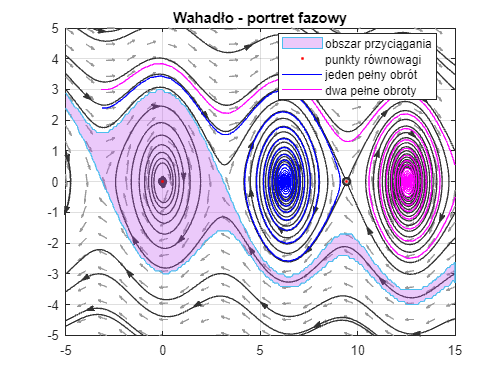

legend([p, r, m, g], ["obszar przyciągania", "punkty równowagi", "jeden pełny obrót", "dwa pełne obroty"], 'Location','best')
title("Wahadło - portret fazowy")
hold off

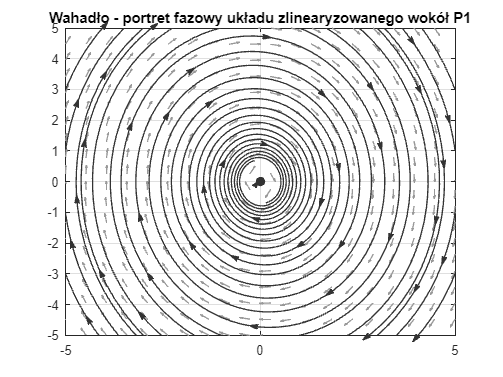

g = 9.81;
c = 2.5;
m = 5;
l = 5;
J = [0 1; -g/l -c/(l*m)];
plotpp(@(t, x)J*[x(1); x(2)])
title("Wahadło - portret fazowy układu zlinearyzowanego wokół P1")

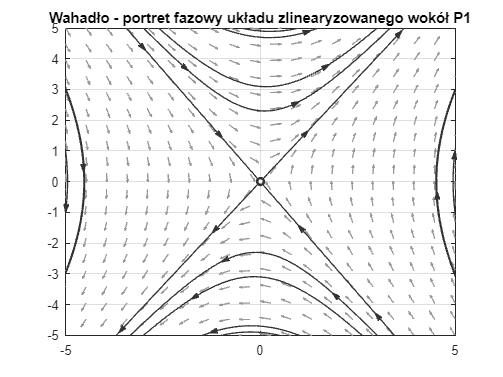

J = [0 1; g/l -c/(l*m)];
plotpp(@(t, x)J*[x(1); x(2)])
title("Wahadło - portret fazowy układu zlinearyzowanego wokół P1")

## Układ Van der Pola


$$\dot{x_{1}} = x_{2} - x_{1}^3 - ax_{1}$$



$$\dot{x_{2}} = -x_{1}$$


clear all
syms x1 x2

a = -3;

J = [-3*x1^2+3 1; -1 0]

$$J = \left(\begin{array}{cc} 3-3\,{x_{1}}^{2} & 1\\ -1 & 0 \end{array}\right)$$

% P(0,0)
J1 = [-a 1; -1 0]

J1 =      3     1
    -1     0


eig(J1)

ans =     2.6180
    0.3820


odefun = @(t, x)system39(t, x, a);
plotpp(odefun)
hold on
w = plot(0.00001, -0.00001, '.', 'Color', 'g')

w =   Line with properties:

              Color: [0 1 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 1.0000e-05
              YData: -1.0000e-05

  Show all properties


r = plot(0, 0, '.', 'Color', 'red', 'MarkerSize',4)

r =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 4
    MarkerFaceColor: 'none'
              XData: 0
              YData: 0

  Show all properties


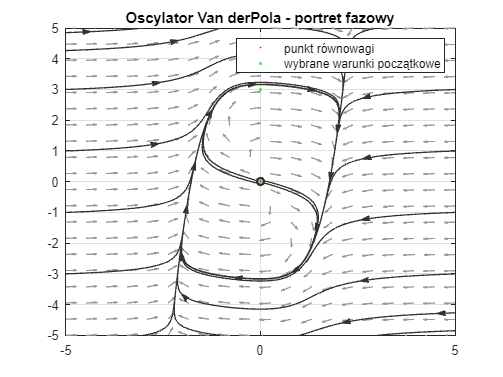

plot(0, 3, '.', 'Color', 'g')
legend([r,w], ["punkt równowagi", "wybrane warunki początkowe"])
title("Oscylator Van derPola - portret fazowy")
hold off

J1 = [-a  1; -1 0]

J1 =      3     1
    -1     0


plotpp(@(t, x)J1*[x(1); x(2)])
hold on
w = plot(0.00001, -0.00001, '.', 'Color', 'g')

w =   Line with properties:

              Color: [0 1 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 1.0000e-05
              YData: -1.0000e-05

  Show all properties


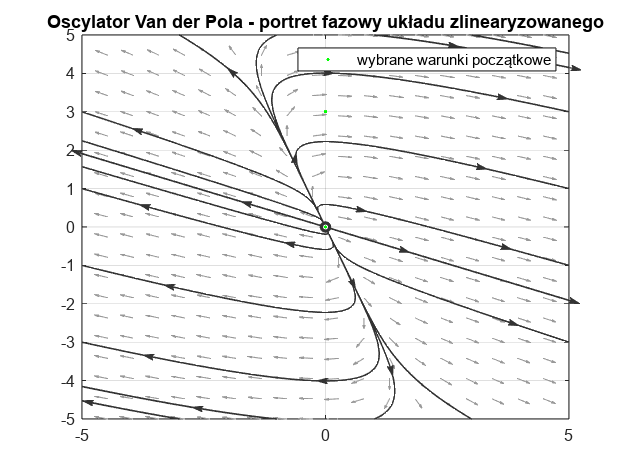

plot(0, 3, '.', 'Color', 'g')
title("Oscylator Van der Pola - portret fazowy układu zlinearyzowanego")
legend(w, "wybrane warunki początkowe")
hold off

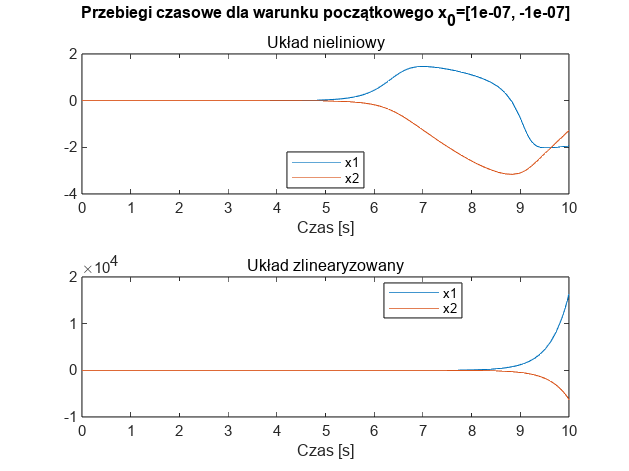

figure 
close all;
clear all;
sim_time = 10;
subplot(2,1,1)
a = -3;
x0=[0.0000001, -0.0000001];
[t, xx] = ode45(@(t,x) system39(t,x,a), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
x=[0,0];
A=[-a, 1; -1, 0];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

%saveas(gcf, 'przebiegi21.png')

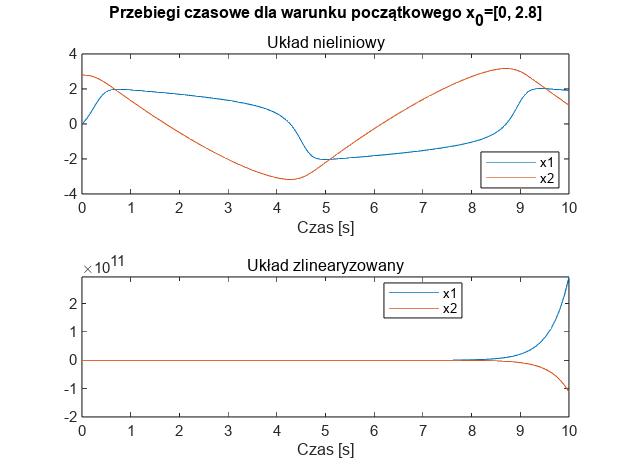

figure 
close all;
clear all;
sim_time = 10;
subplot(2,1,1)
a = -3;
x0=[0, 2.8];
[t, xx] = ode45(@(t,x) system39(t,x,a), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
x=[0,0];
A=[-a, 1; -1, 0];
T=6;
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

%saveas(gcf,'przebiegi22.png')

function dxdt = system31(t, x, b, c, d)
    dxdt = zeros(2, 1);
    dxdt(1) = x(2);
    dxdt(2) = -c*x(1) - d*x(1)^3 - b*x(2);
end %system31


function dxdt = system38(t, x, c, l, m)
    dxdt = zeros(2, 1);
    dxdt(1) = x(2);
    dxdt(2) = -9.81/l * sin(x(1)) - c/(l*m) * x(2);
end %system38


function dxdt = system39(t, x, a)
    dxdt = zeros(2, 1);
    dxdt(1) = x(2) - x(1)^3 - a*x(1);
    dxdt(2) = -x(1);
end %system39